A = [0 1 0 0;
    2 0 0 0;
    0 0 0 1;
    0 0 6 0];
B = [0 0;
    -2 -2;
    0 0;
    -1 1];
C = [1 0 6 0;
    1 0 -6 0];
C_des = [1 0 0 0; 0 0 1 0];
D = [0,0;0,0];
M = 1/2 * [1 1; 1 -1];
Bv = B / M;

% Q and R, waiting for tuning
Q = diag([100,1,200,1]);
R = diag([1,1]);
t = linspace(0,5,100);

Kv = lqr(A,Bv,Q,R);
K =  M \ Kv;
Acl = A - B * K;
G = -inv(C_des / Acl * Bv);

% print out closed loop eigenvalue locations
format short
closed_loop_evalues =  eig(Acl)

closed_loop_evalues =   -5.0025 + 3.8762i
  -5.0025 - 3.8762i
  -4.2961 + 3.2337i
  -4.2961 - 3.2337i



const_p9= zeros([1,length(t)]);
const_1p05 = zeros(size(const_p9));
for i=1:length(t)
    const_p9(i) = .9;
    const_1p05(i) = 1.05;
end

%  sys = G * C_des *(S *I - Acl) *B 
% s = tf('s');
% sys = minreal(G * C_des / (s * eye(4) - Acl ) * B

Check Response and Plot 

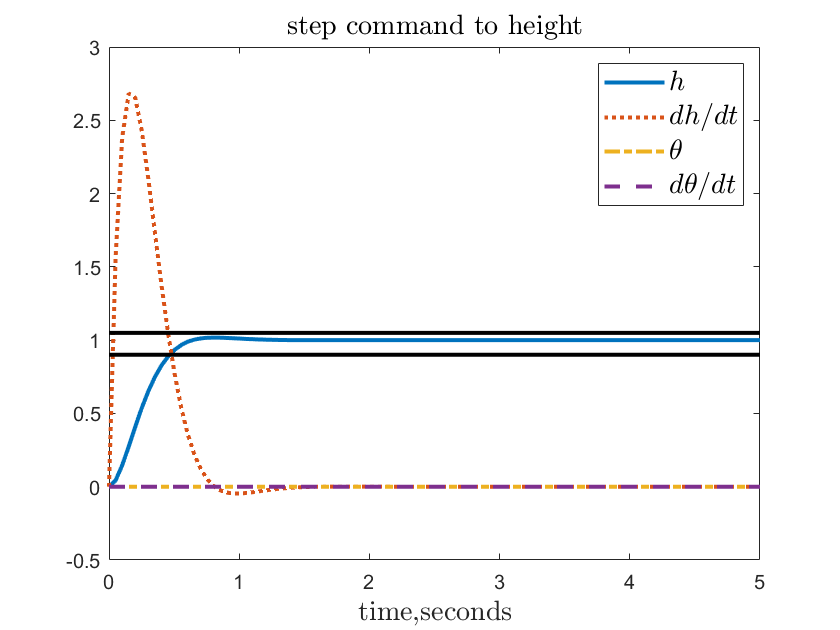

% x = step(Acl, G, C_des, D,[],t);
x = step(Acl,Bv * G, eye(4), zeros([4,2]),1,t);

figure(1)
clf

plot(t,x(:,1)','-',t,x(:,2)',':',t,x(:,3)','-.',...
              t,x(:,4)','--',t,const_p9','k-',t,const_1p05','k-')
h = legend('$h$','$dh/dt$','$\theta$','$d\theta/dt$');
hh = title('step command to height');
hhh = xlabel('time,seconds');
set(h,'interpreter','latex','fontsize',14);
set(hh,'interpreter','latex','fontsize',14);
set(hhh,'interpreter','latex','fontsize',14);
set(findall(gcf,'type','line'),'linewidth',2);

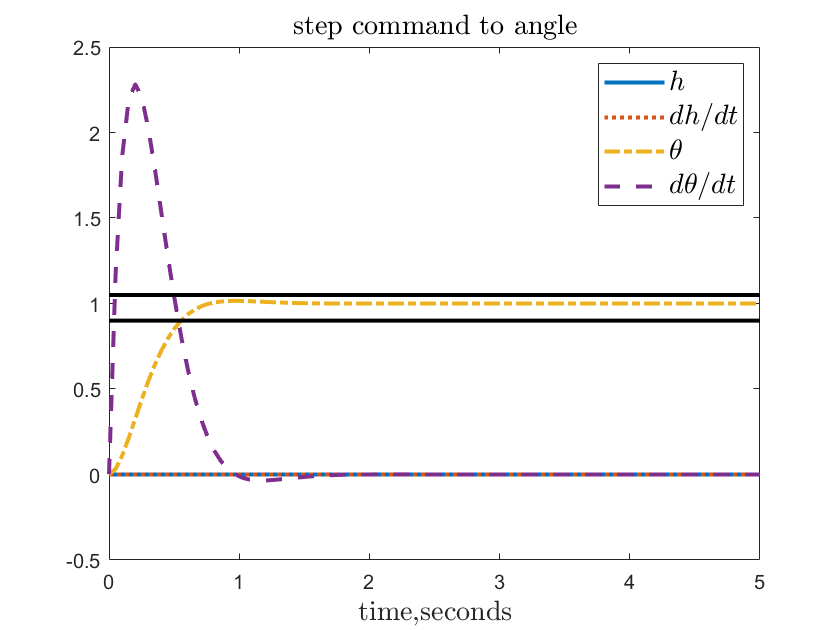



% calculate response of the state vector to a step command in angle
x = step(Acl,Bv * G, eye(4), zeros([4,2]),2,t);

figure(2)
clf
 
plot(t,x(:,1)','-',t,x(:,2)',':',t,x(:,3)','-.',...
          t,x(:,4)','--',t,const_p9','k-',t,const_1p05','k-')
h = legend('$h$','$dh/dt$','$\theta$','$d\theta/dt$');
hh = title('step command to angle');
hhh = xlabel('time,seconds');
set(h,'interpreter','latex','fontsize',14);
set(hh,'interpreter','latex','fontsize',14);
set(hhh,'interpreter','latex','fontsize',14);
set(findall(gcf,'type','line'),'linewidth',2)

Part E

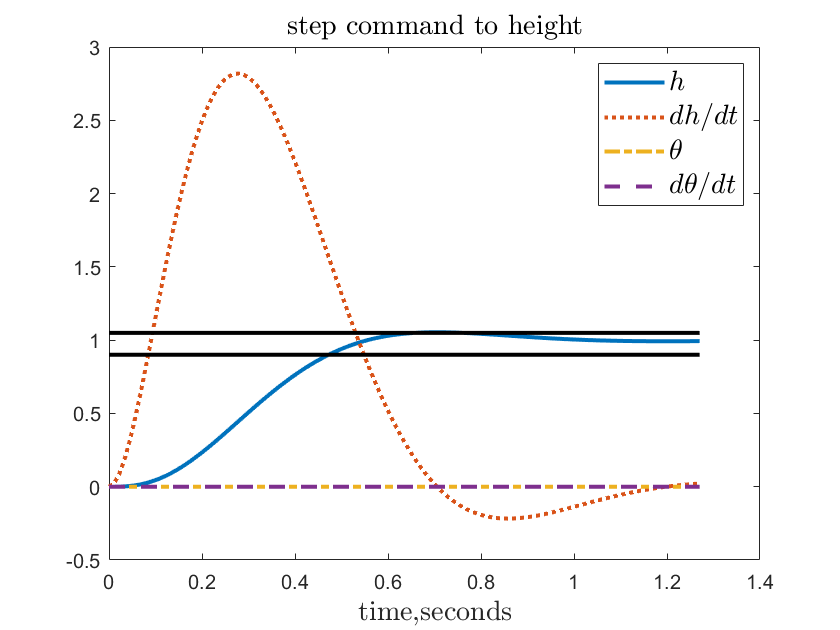

% Plant augmented with integrators

Aaug =  [A, zeros([4,2])
        C, zeros([2,2])];
Baug =  [B;zeros([2,2])];
Caug =  [C,zeros([2,2])];
Daug =  zeros([2,2]);

%  transformation matrix from states [h;theta] to outputs [y1;y2]

H =  [1, 6; 1, -6];  % given in the context 

% weighting matrices, given in the context
Qx = diag([20000,60000]);
Qy = H' \ Qx / H;
Qaug =  [Q,zeros([4,2]);zeros([2,4]),Qy];

% compute the optimal state feedback
Kaug = lqr(Aaug, Baug,Qaug,R);

% print out closed loop eigenvalues
% format short e
closed_loop_evalues = eig(Aaug-Baug*Kaug);
Aclaug = Aaug - Baug * Kaug;
Bclaug = [zeros([4,2]);-H];
[y,x,t] = step(Aclaug,Bclaug,Caug,Daug ,1);
clear const_p9 const_1p05
for i=1:length(t)
   const_p9(i) = .9;
  const_1p05(i) = 1.05;
end

figure(1)
clf
 
plot(t,x(:,1),'-',t,x(:,2),':',t,x(:,3),'-.',t,x(:,4),'--',t,const_p9,'k-',t,const_1p05,'k-')
h = legend('$h$','$dh/dt$','$\theta$','$d\theta/dt$');
hh = title('step command to height');
hhh = xlabel('time,seconds');
set(h,'interpreter','latex','fontsize',14);
set(hh,'interpreter','latex','fontsize',14);
set(hhh,'interpreter','latex','fontsize',14);
set(findall(gcf,'type','line'),'linewidth',2)

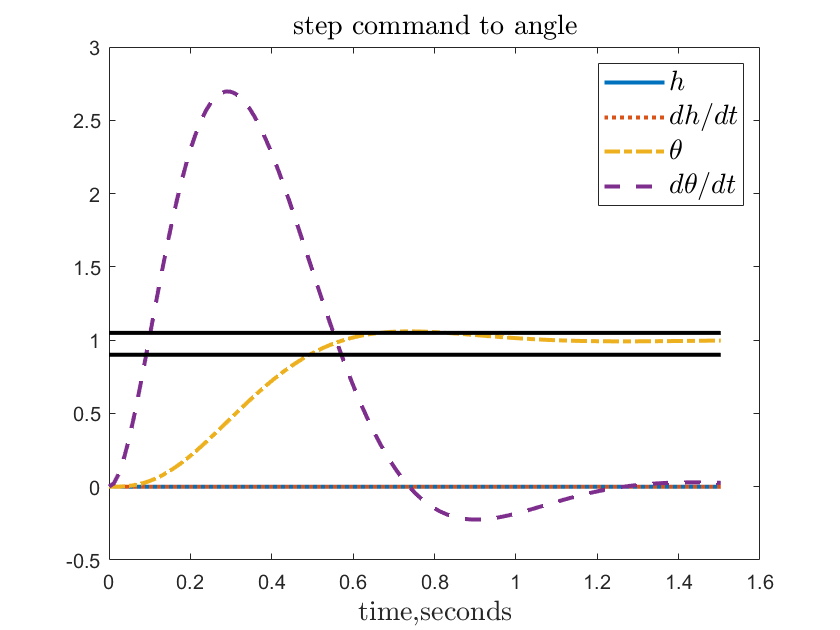




% step command to theta
[y,x,t] = step(Aclaug,Bclaug,Caug,Daug ,2);
clear const_p9  const_1p05
for i=1:length(t)
  const_p9(i) = .9;
  const_1p05(i) = 1.05;
end

figure(2)
clf
 
plot(t,x(:,1),'-',t,x(:,2),':',t,x(:,3),'-.',t,x(:,4),'--',t,const_p9,'k-',t,const_1p05,'k-')
h = legend('$h$','$dh/dt$','$\theta$','$d\theta/dt$');
hh = title('step command to angle');
hhh = xlabel('time,seconds');
set(h,'interpreter','latex','fontsize',14);
set(hh,'interpreter','latex','fontsize',14);
set(hhh,'interpreter','latex','fontsize',14);
set(findall(gcf,'type','line'),'linewidth',2)